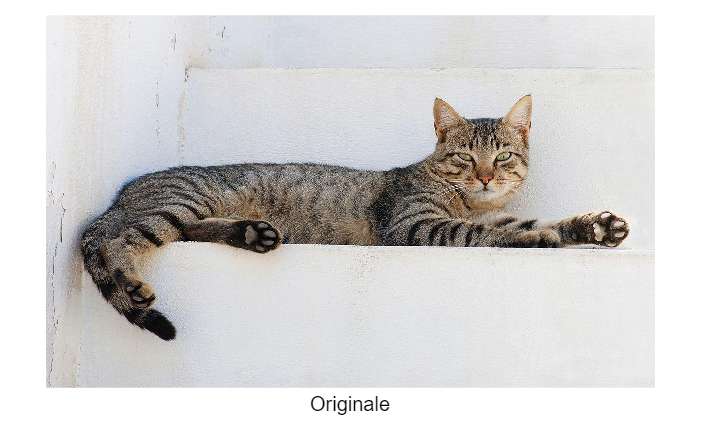

fullFileName = matlab.desktop.editor.getActiveFilename;
folderPath = fileparts(fullFileName);
folderPath = strrep(folderPath, 'MatLab', '');
folderPath = fullfile(folderPath, 'Python/dataset');
folderPath = fullfile(folderPath, 'original');
nome_img = 'Cat_August_2010-4.jpg';
folderPath = fullfile(folderPath, nome_img);

i2 = imread(folderPath);

imshow(i2)
text(size(i2,2)/2, size(i2,1) + 10, 'Originale', ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 12);

Normalizzazione

img = im2double(img);

Applicazione del rumore di tipo Poisson

scale = 255;  % Fattore di scala (es. numero massimo di conteggi)
% Il parametro di scala serve per fornire dei valoi validi di lamba per la
% distribuzione di Poisson
img_scaled = img * scale;

% Genera rumore Poisson
img_poisson_counts = poissrnd(img_scaled);

img_poisson = img_poisson_counts / scale;

Mostra immagine con Rumore

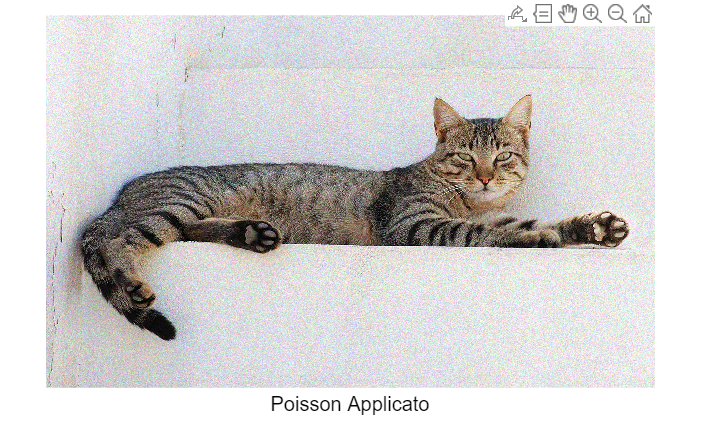

imshow(img_poisson)
text(size(i2,2)/2, size(i2,1) + 10, 'Poisson Applicato', ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 12);